samplerate = 16e3;
t = (-320:320)'/samplerate;
w0 = 2*pi*100;
T = 2*pi/w0;
disp(T/4)

    0.0025



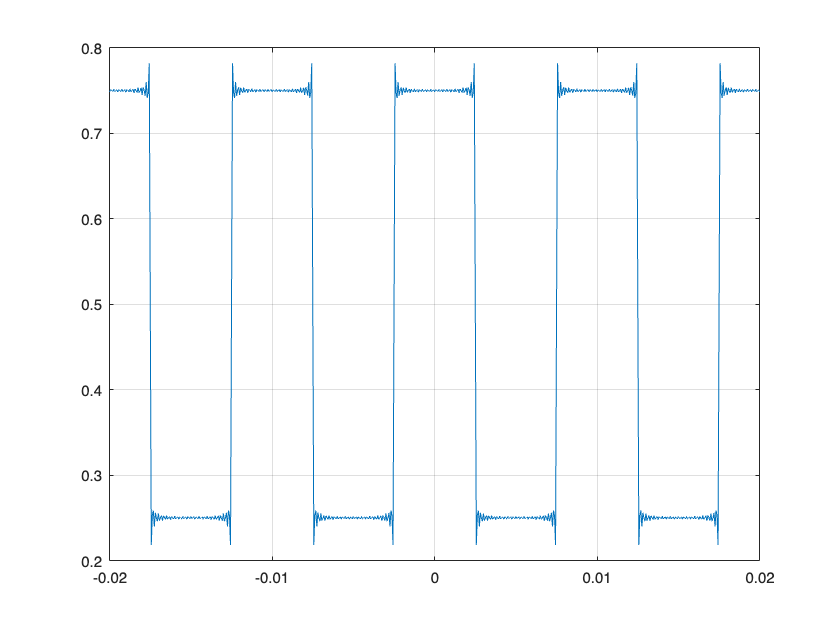

% SFC com deslocamento temporal de T1
ak = @(k) sin(k*w0*T/4)./(k*2*pi);
a0 = 1/2;   % Segregate a0, which often has a different expression
N = 100;    % Order of the Fourier expansion
xN = exp(1i*w0*t*(-N:N))*[ak(-N:-1) a0 ak(1:N)].';
plot(t,real(xN)); grid

Os detalhes da forma do sinal demonstram que a SFC é convergente pois verifica-se que é absolutamente integrável tem um número finito de máximos e mínimos num período e um número finito de descontinuidades num intervalo de tempo finito 

NÃO SEI SE É BEM ISTO QUE SE OBSERVA??